## 3.2

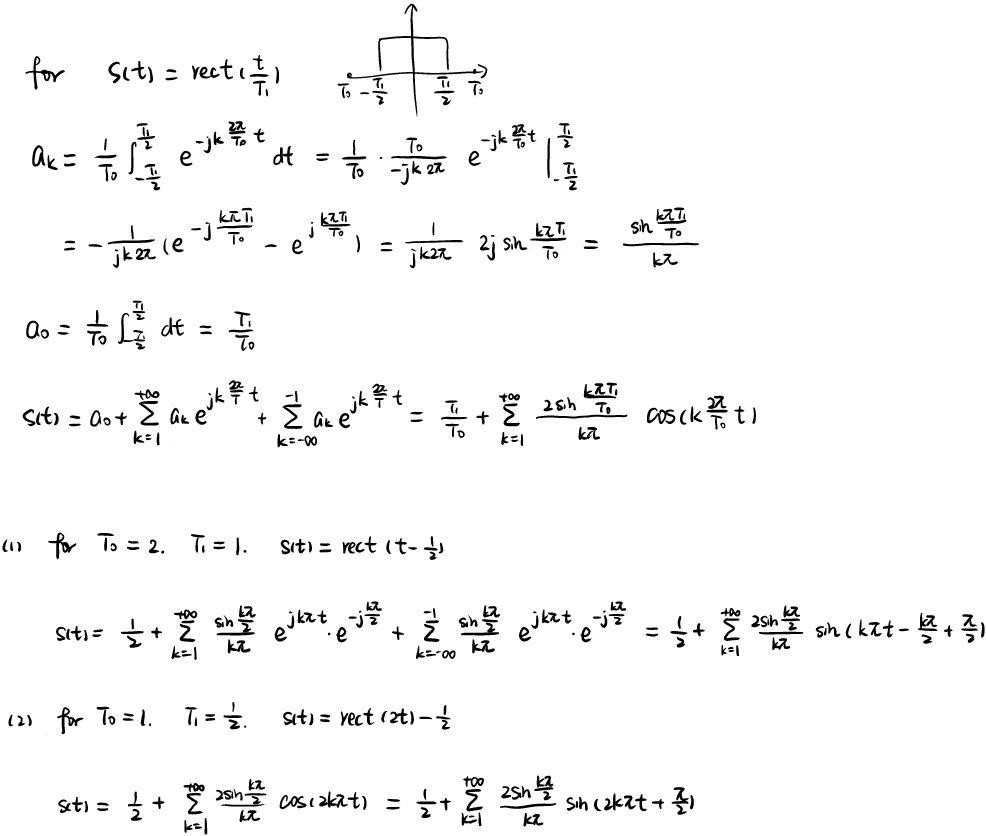

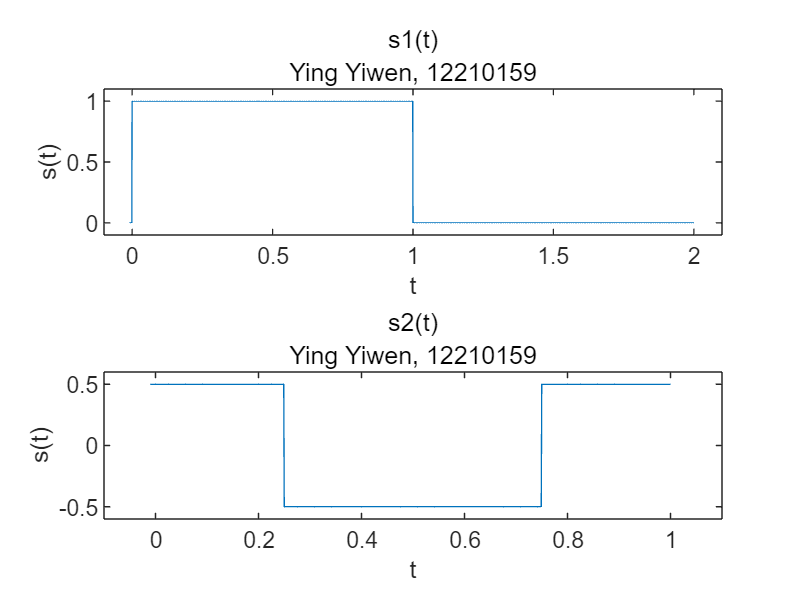

t=-0.01:0.001:2;
s=(t>=0)-(t>=1);
figure;
subplot(2,1,1),plot(t,s),xlim([-0.1 2.1]),ylim([-0.1 1.1]),title('s1(t)','Ying Yiwen, 12210159'),xlabel('t'),ylabel('s(t)');
t=-0.01:0.001:1;
s=(t>=-0.25)-(t>=0.25)+(t>=0.75)-0.5;
subplot(2,1,2),plot(t,s),xlim([-0.1 1.1]),ylim([-0.6 0.6]),title('s2(t)','Ying Yiwen, 12210159'),xlabel('t'),ylabel('s(t)');

## 3.5

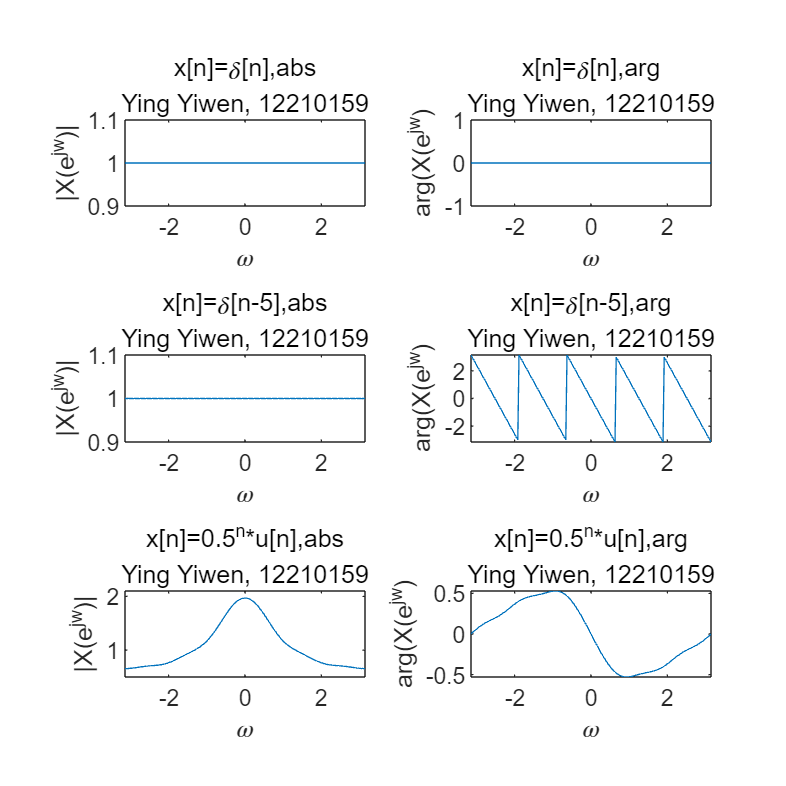

n = -5:5;
n0 = -5;
dw = pi/100;
x1 = (n==0);
x2 = (n==5);
x3 = (0.5.^n).*(n>=0);
X1 = DTFT(x1,n0,dw);
X2 = DTFT(x2,n0,dw);
X3 = DTFT(x3,n0,dw);
figure;
set(gcf, 'Position', [100, 100, 1000, 1000]);
subplot(3,2,1),plot(-pi:dw:pi,abs(X1)),xlabel('\omega'),ylabel('|X(e^{jw})|'),title('x[n]=\delta[n],abs','Ying Yiwen, 12210159'),ylim([0.9 1.1]);
subplot(3,2,2),plot(-pi:dw:pi,angle(X1)),xlabel('\omega'),ylabel('arg(X(e^{jw})'),title('x[n]=\delta[n],arg','Ying Yiwen, 12210159');
subplot(3,2,3),plot(-pi:dw:pi,abs(X2)),xlabel('\omega'),ylabel('|X(e^{jw})|'),title('x[n]=\delta[n-5],abs','Ying Yiwen, 12210159'),ylim([0.9 1.1]);
subplot(3,2,4),plot(-pi:dw:pi,angle(X2)),xlabel('\omega'),ylabel('arg(X(e^{jw})'),title('x[n]=\delta[n-5],arg','Ying Yiwen, 12210159');
subplot(3,2,5),plot(-pi:dw:pi,abs(X3)),xlabel('\omega'),ylabel('|X(e^{jw})|'),title('x[n]=0.5^n*u[n],abs','Ying Yiwen, 12210159'),ylim([0.5 2.1]);
subplot(3,2,6),plot(-pi:dw:pi,angle(X3)),xlabel('\omega'),ylabel('arg(X(e^{jw})'),title('x[n]=0.5^n*u[n],arg','Ying Yiwen, 12210159');

function X=DTFT(x,n0,dw)
    w = -pi:dw:pi;
    X = 0;
    for n = 1:length(x)
        X = X + x(n)*exp(-1j*w*(n+n0-1));
    end
end